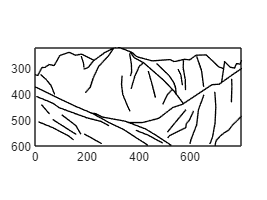

% Add path and load the data structure(vecLD)
addpath(genpath('scripts'));
load('dataSets/TorontoScenes/mountains_vecLD.mat');

% Choose one image for demonstration 
% We use data structure 11 here (row 11) and call it 'cute'!
cute = vecLD(11);
% View 'cute'
drawLinedrawing(cute)

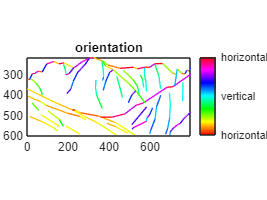

% Compute contour properties for 'cute'
% default: {'orientation','length','curvature','junctions'}
% You can specify what properties to compute
% computeContourProperties(vecLD,whichProps)
cute = computeContourProperties(cute);

% Visualize properties separately
figure;drawLinedrawingProperty(cute,'orientation');
title('orientation');

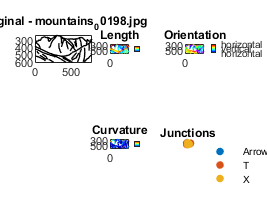


% Visualize all the properties
drawAllProperties(cute);

% Get contour properties histograms
% [vecLD,histograms,bins,statsShortNames] = getContourPropertiesStats(vecLD, whichStats)
% Input:
%   cute - vecLD data structure
%   whichStats - defines which properties to compute
%                default: {'orientation','length','curvature','junctions'}
%   minmaxLen - this minimum and maximum for the length histogram 
%               (default: [2, width+length of the image])
%   minmaxCurv- this minimum and maximum for the curvature histogram 
%               default: [0, 90]
%   junctionTypes - a cell array with the junction types to incldue in the histogram
%                   default: {} - use all jucniton types present in this
%                   image
%
% Output:
%   cute -       vecLD with the individual contour stats added
%   histograms - cell array of histograms for the features 
%                in the same order as in whichstats
%   bins -       cell array of bin centers for those histograms
%                in the same order as in whichstats
%   statsShortNames - the order of stats in the histgrams and bins
[cute,histograms,bins,shortStats] = getContourPropertiesStats(cute);

% Convert histograms into table
cutetable = convertHistogramsToTable(histograms,bins,shortStats)

cutetable = 1×37 table
    ori_1     ori_2     ori_3    ori_4     ori_5     ori_6     ori_7     ori_8     len_1    len_2    len_3    len_4     len_5     len_6     len_7     len_8     curv_1    curv_2    curv_3    curv_4    curv_5    curv_6    curv_7    curv_8    juncType_T    juncType_Y    juncType_X    juncType_Arrow    juncType_Star    juncAngle_1    juncAngle_2    juncAngle_3    juncAngle_4    juncAngle_5    


% Export table to csv
writetable(cutetable,'User_test/cutable.csv');

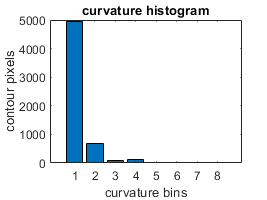

% Bar graph of histograms
figure;
bar(cute.sumCurvatureHistogram);
title('curvature histogram');
xlabel('curvature bins')
ylabel('contour pixels');

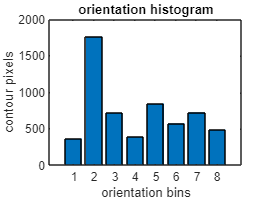


figure;
bar(cute.sumOrientationHistogram);
title('orientation histogram');
xlabel('orientation bins')
ylabel('contour pixels');

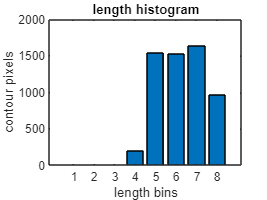


figure;
bar(cute.sumLengthHistogram);
title('length histogram');
xlabel('length bins')
ylabel('contour pixels');

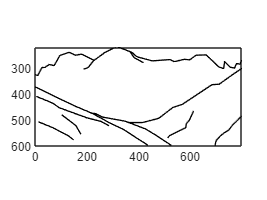

% Split image into two versions based on selected properties
% Split image by curvature and orientation (50% proportion of pixels)
[top2,bottom2] = splitLDbyProperties(cute,{'curvature', 'orientation'},0.5,[1,1]);
figure;
drawLinedrawing(top2);

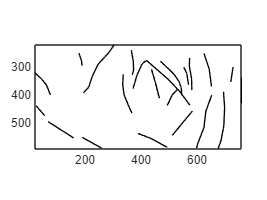

figure;
drawLinedrawing(bottom2);

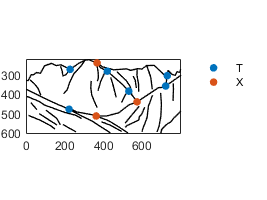

% split image into two versions based on histogram weights
% Split image by T junctions (50% proportion of pixels)
% Weights argument in the splitLDbyProperties is used to select junction
% type according to the following order: T,Y,X,Arrow,Star
[top1,bottom1] = splitLDbyHistogramWeights(cute,'junctions',0.5,{[1,0,0,0,0]}); 
figure;
drawLinedrawing(top1);
figure;
drawLinedrawing(bottom1);

% Visualize T junctions overlayed on split version (top) with top 50% of pixels
% that include at least 1 T junction 
figure;
drawLinedrawing(top1);
drawJunctions(top1.junctions,{'T'});

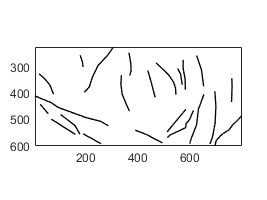


% Visualize T junctions overlayed on split version (bottom) with bottom 50% of pixels
% that include at least 1 T junction 
figure;
drawLinedrawing(bottom1);

drawJunctions(bottom1.junctions,{'T'});

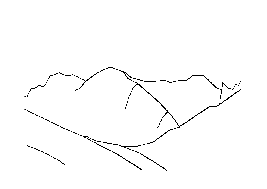

%save split versions of images to output folder
imageTop = renderLinedrawing(top1,[],[],3);
imshow(imageTop)

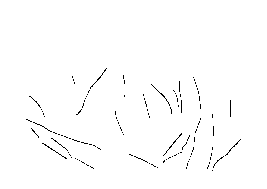

imwrite(imageTop,'User_test/Output/imageTop.png')

imageBottom = renderLinedrawing(bottom1,[],[],3);
imshow(imageBottom)

imwrite(imageBottom,'User_test/Output/imageBottom.png')
